# Notebook 03: ANN Training

This research project contains 3 notebooks:

- Notebook 01: Project Overview

- Notebook 02: Preprocessing and Feature Extraction

- Notebook 03: ANN Training

You are currently running **Notebook 03**. Before running this notebook, you should have run Notebook 02 to generate features from the neural data.

## Step 0: Ensure you are in the correct directory

cd(fileparts(matlab.desktop.editor.getActiveFilename))

## Step 1: Load the neural features

Before proceeding, ensure you've run the last cell of the Feature Extraction section in `notebook 02`, which saves your neural features to the `results` folder in your workspace.

clearvars
load("datasets\training_dataset.mat")
load("results\features.mat")

## Step 2: Determine the dimensions of the mapping

For this section, you have been provided with a Multilayer Feedforward Network. You are welcome to use your own architecture, but the explanations in this notebook only apply to the provided network.

Remember that a neural network can be thought of as a [universal function approximator.](https://www.cs.cmu.edu/~epxing/Class/10715/reading/Kornick_et_al.pdf) This means that your network learns a one-to-one mapping between your input vectors and your output vectors:


$$\vec{x_{out}} = f(\vec{x_{in}})$$


For this reason, you must ensure that the network has the same number of input vectors as output vectors during training.

Your output vectors are the hand's kinematics, which are a set of `N` vectors with dimensionality `1x2.`

Your input vectors are a set of `N` vectors with dimensionality `1xM`, where `M` is determined by your feature extraction methods.

`N,` in this case, corresponds to the number of samples in the `hand_kinematics` of the training set.

First, verify that your have the same number of samples for the features and the kinematics, which will act as our feature labels (i.e., the values we are trying to predict).  

feature_labels = training_data.hand_kinematics;
features = neural_features;
assert(length(features) == length(feature_labels));

How many outputs do we want? Well, that depends on the number of degrees of freedom we are predicting, which in our case is:

n_outputs = width(feature_labels)

n_outputs = 2

How many features per sample do you have in total? That depends on the choices you made in `notebook_02`, including but not limited to:

- How many channels (out of the six provided in the dataset) you decided to use

- How many features per channel you calculated

n_features = width(features');

How many timestamps are there?

n_timestamps = length(neural_features);

After providing this information, we know that **for every timestamp** in features:

fprintf('Your neural network will map a %dx1 vector to a %dx1 vector', n_features, n_outputs)

Your neural network will map a 1x1 vector to a 2x1 vector

## Step 3: Implement and train the neural network

### A) Reshape input features

Due to MATLAB's limited selection of [input layers](https://www.mathworks.com/help/deeplearning/ug/list-of-deep-learning-layers.html), we will be using the [`imageInputLayer`](https://www.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.imageinputlayer.html) option, even though we are not necessarily working with image data.

This requires that we reshape our features by adding additional "dummy" dimensions to satisfy the `imageInputLayer` API.

image_input_size = [n_features, 1, 1];
reshaped_features = zeros([image_input_size, n_timestamps]);
for timestamp = 1:n_timestamps
    reshaped_features(:,:,:, timestamp) = features(:,timestamp);
end

### B) Declare the architecture layers

The following is a feedforward neural network, which is the simplest form of a neural network. It is made of fully connected layers of perceptrons with activation layers in between (tanhLayer). 

% Feel free to change the architecture
network_layers = [ ...
    imageInputLayer(image_input_size)
    fullyConnectedLayer(n_features*2)
    tanhLayer
    fullyConnectedLayer(n_features*3)
    tanhLayer
    fullyConnectedLayer(n_features*3)
    tanhLayer
    fullyConnectedLayer(n_features*2)
    tanhLayer
    fullyConnectedLayer(n_outputs)
    regressionLayer
    ]

network_layers =   11×1 Layer array with layers:

     1   ''   Image Input         1×1×1 images with 'zerocenter' normalization
     2   ''   Fully Connected     2 fully connected layer
     3   ''   Tanh                Hyperbolic tangent
     4   ''   Fully Connected     3 fully connected layer
     5   ''   Tanh                Hyperbolic tangent
     6   ''   Fully Connected     3 fully connected layer
     7   ''   Tanh                Hyperbolic tangent
     8   ''   Fully Connected     2 fully connected layer
     9   ''   Tanh                Hyperbolic tangent
    10   ''   Fully Connected     2 fully connected layer
    11   ''   Regression Output   mean-squared-error

### C) Train the neural network

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:03 |         0.92 |          0.4 |          0.1000 |
|       1 |          50 |       00:00:04 |         0.40 |      7.8e-02 |          0.1000 |
|       1 |         100 |       00:00:04 |         0.39 |      7.6e-02 |          0.1000 |
|       1 |         150 |       00:00:05 |         0.37 |      6.9e-02 |          0.1000 |
|       1 |         200 |       00:00:05 |         0.41 |      8.5e-02 |          0.1000 |
|       1 |         250 |       00:00:06 |         0.41 |      8.4e-02 |          0.1000 |
|       1 |         300 |  

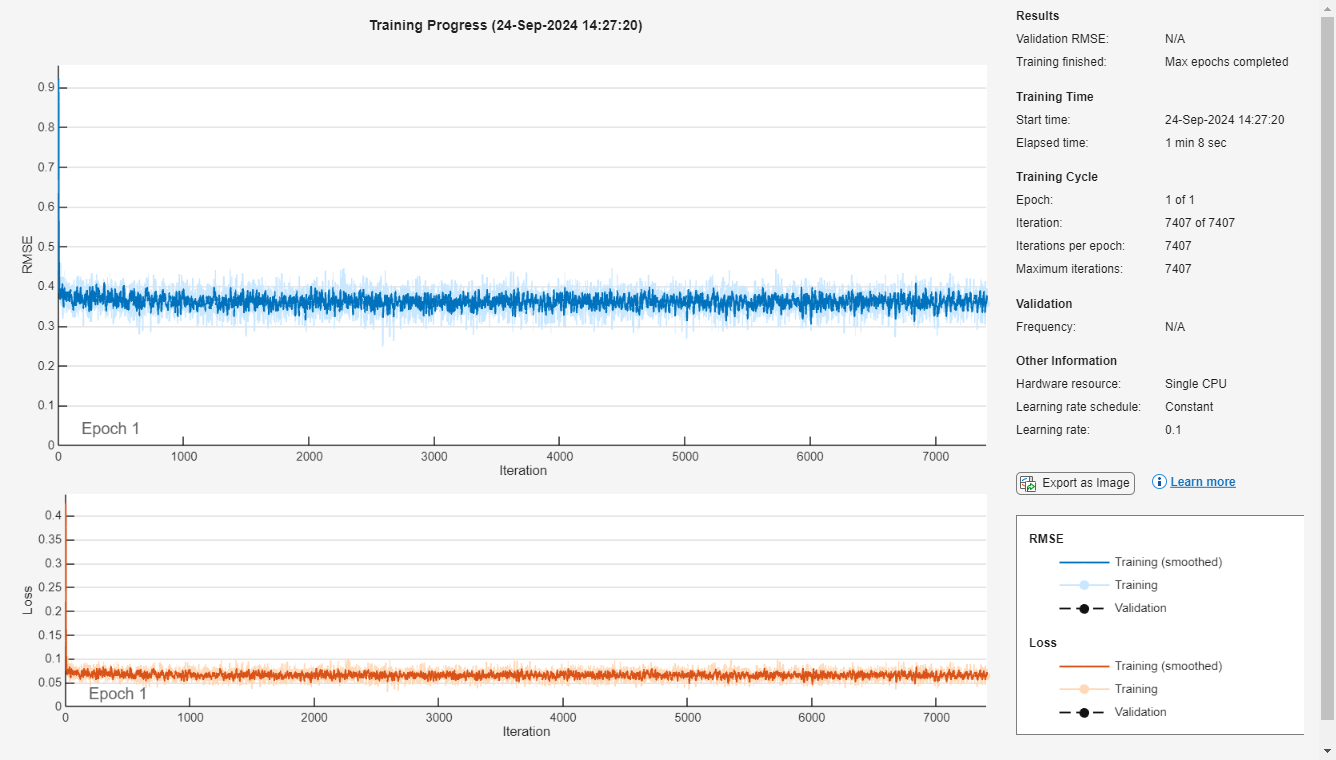

neural_net =   SeriesNetwork with properties:

         Layers: [11×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'regressionoutput'}


% Feel free to experiment with the training options
training_options = trainingOptions( "sgdm", ...
                                    InitialLearnRate=0.1, ...
                                    MaxEpochs=1, ...
                                    Shuffle="every-epoch", ...
                                    Plots="training-progress");
neural_net = trainNetwork(reshaped_features, feature_labels, network_layers, training_options)

## Step 4: Test the neural network against unseen data

### A) Load the testing dataset

load("datasets\testing_dataset.mat")
sample_rate = 10000

sample_rate = 10000

You need to apply the same preprocessing steps as you did for your training data

### B) Filter the data

Refer to **Step 3** of the **Preprocessing** section in **Notebook 2**.

%%%%%%%%%%%%%%%%%%%%%%%%% CHANGE THIS CODE %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
[b1, a1] = butter(4,[15, 550]/ (sample_rate/2),'bandpass')

b1 =     0.0005         0   -0.0021         0    0.0032         0   -0.0021         0    0.0005


a1 =     1.0000   -7.1118   22.1660  -39.5555   44.2122  -31.6995   14.2389   -3.6636    0.4134



%[b2, a2] = butter(4,500/ (sample_rate/2),'low')
ch_init_conds = zeros(8, 6); %initial conditions for filter for all channels

[filt_neural_data1, ~] = FilterX(b1, a1, testing_data.raw_neural_data,ch_init_conds);
%[filt_neural_data, ~] = FilterX(b2, a2, filt_neural_data, zeros(4, 6) );
%[b3, a3] = butter(4,250/ (sample_rate/2),'low')
d = designfilt('bandstopiir','FilterOrder',2, ...
               'HalfPowerFrequency1',59,'HalfPowerFrequency2',61, ...
               'DesignMethod','butter','SampleRate',sample_rate);
d2 = designfilt('bandstopiir','FilterOrder',2, ...
               'HalfPowerFrequency1',119,'HalfPowerFrequency2',121, ...
               'DesignMethod','butter','SampleRate',sample_rate);
d3 = designfilt('bandstopiir','FilterOrder',2, ...
               'HalfPowerFrequency1',179,'HalfPowerFrequency2',181, ...
               'DesignMethod','butter','SampleRate',sample_rate);
filt_neural_data1= filtfilt(d,filt_neural_data1);
filt_neural_data1= filtfilt(d2,filt_neural_data1);
filt_neural_data1= (filtfilt(d3,filt_neural_data1));
[b2, a2] = butter(4,[500, 2000]/ (sample_rate/2),'bandpass')

b2 =     0.0186         0   -0.0743         0    0.1114         0   -0.0743         0    0.0186


a2 =     1.0000   -4.4207    9.1198  -11.6348   10.1195   -6.1167    2.4910   -0.6263    0.0762



%[b2, a2] = butter(4,500/ (sample_rate/2),'low')
ch_init_conds = zeros(8, 6); %initial conditions for filter for all channels

[filt_neural_data2, ~] = FilterX(b2, a2, testing_data.raw_neural_data,ch_init_conds);
%[filt_neural_data, ~] = FilterX(b2, a2, filt_neural_data, zeros(4, 6) );
%[b3, a3] = butter(4,250/ (sample_rate/2),'low')
d = designfilt('bandstopiir','FilterOrder',2, ...
               'HalfPowerFrequency1',59,'HalfPowerFrequency2',61, ...
               'DesignMethod','butter','SampleRate',sample_rate);
d2 = designfilt('bandstopiir','FilterOrder',2, ...
               'HalfPowerFrequency1',119,'HalfPowerFrequency2',121, ...
               'DesignMethod','butter','SampleRate',sample_rate);
d3 = designfilt('bandstopiir','FilterOrder',2, ...
               'HalfPowerFrequency1',179,'HalfPowerFrequency2',181, ...
               'DesignMethod','butter','SampleRate',sample_rate);
filt_neural_data2= filtfilt(d,filt_neural_data2);
filt_neural_data2= filtfilt(d2,filt_neural_data2);
filt_neural_data2= (filtfilt(d3,filt_neural_data2));
%butter(filt_order, norm_cut_off, 'high'); % 4th order highpa

n = 5000

n = 5000

window = ones([1,n]);
buffer1 = zeros([1,948198]);
buffer2 = zeros([1,948198]);
spike_locations1 = (abs(filt_neural_data1(:,1))> 7.5);

spike_locations2 = (abs(filt_neural_data2(:,1))> 5.5);
for i  = 10:length(buffer2)-n;
    if i< length(buffer2)/2;
       buffer2(i) = sum(spike_locations2((i):(n+i),1))/n;
    
    
        if buffer2(i)> 0.1*0.2;
            buffer2(i) = 5*buffer2(i);
        end
    
        if buffer2(i)>0.148*0.3;
           buffer2(i) = 0.1485;
        end    
    end
 
  

end
for i  = 10:length(buffer2)-n;
    if i> length(buffer2)/2;
       buffer1(i) = sum(spike_locations1((i):(n+i),1))/n;
    
    
        if buffer1(i)> 0.1*0.2;
            buffer1(i) = 5*buffer1(i);
        end
    
        if buffer1(i)>0.148*0.3;
           buffer1(i) = 0.1485;
        end    
    end
 
  

end

neural_features = buffer1' + buffer2'

neural_features =          0
         0
         0
         0
         0
         0
         0
         0
         0
    0.0200


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

### C) Generate neural features from the testing dataset

Refer to the **Feature Extraction** section in **Notebook 2.**

%%%%%%%%%%%%%%%%%%%%%%%%% CHANGE THIS CODE %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% nonsensical code that passes the assertion below
length(testing_data.hand_kinematics)

ans = 948198

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
assert(length(neural_features) == length(testing_data.hand_kinematics), "EXPECTED EQUAL LENGTH!")
neural_features = normalize(neural_features, "range", [0 1]);

### D) Reshape the neural features

Refer to **Step 3** of **Notebook 3**

n_features = width(neural_features);
n_timestamps = length(testing_data.hand_kinematics);
image_input_size = [n_features, 1, 1];
reshaped_features = zeros([image_input_size, n_timestamps]);
for timestamp = 1:n_timestamps
    reshaped_features(:,:,:, timestamp) = neural_features(timestamp,:);
end
length(reshaped_features)

ans = 948198

### E) Predict the testing kinematics based on your generated features

kinematics_predicted = predict(neural_net, reshaped_features);
kinematics_observed = training_data.hand_kinematics;

### D) Compare your predictions with the actual values of the kinematics

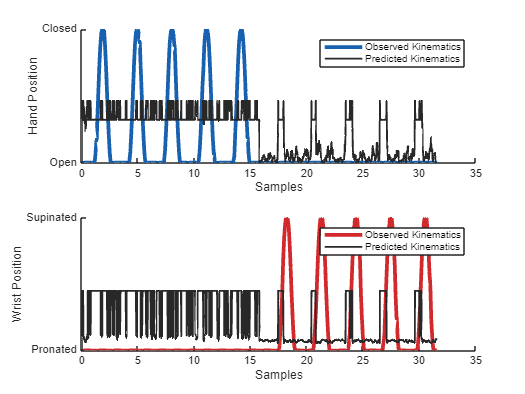

figure
tlo = tiledlayout('flow');
t = (0:1:length(kinematics_observed)-1)/testing_data.sample_rate;
nexttile
hold on
plot(t, kinematics_observed(:,1), 'LineStyle','-','Color', "#1761B0", 'LineWidth', 3)
plot(t, [0;kinematics_predicted(:,1)], 'LineStyle','-','Color', "#282828", 'LineWidth', 1.5)
hold off
xlabel("Samples")
ylabel("Hand Position")
yticks([0 1])
yticklabels({"Open" "Closed"})
legend(["Observed Kinematics", "Predicted Kinematics"])

nexttile
hold on
plot(t, kinematics_observed(:,2), 'LineStyle','-','Color', "#D2292D", 'LineWidth', 3)
plot(t, [0;kinematics_predicted(:,2)], 'LineStyle','-','Color', "#282828", 'LineWidth', 1.5)
hold off
legend(["Observed Kinematics", "Predicted Kinematics"])
xlabel("Samples")
ylabel("Wrist Position")
yticks([0 1])
yticklabels({"Pronated" "Supinated"})
legend(["Observed Kinematics", "Predicted Kinematics"])